# TEST CAPACITA' UTILIZZATORE NELL' EFFETTUARE UNA TRAIETTORIA TARGET

clear all
clc

#### Identifica i bordi del target

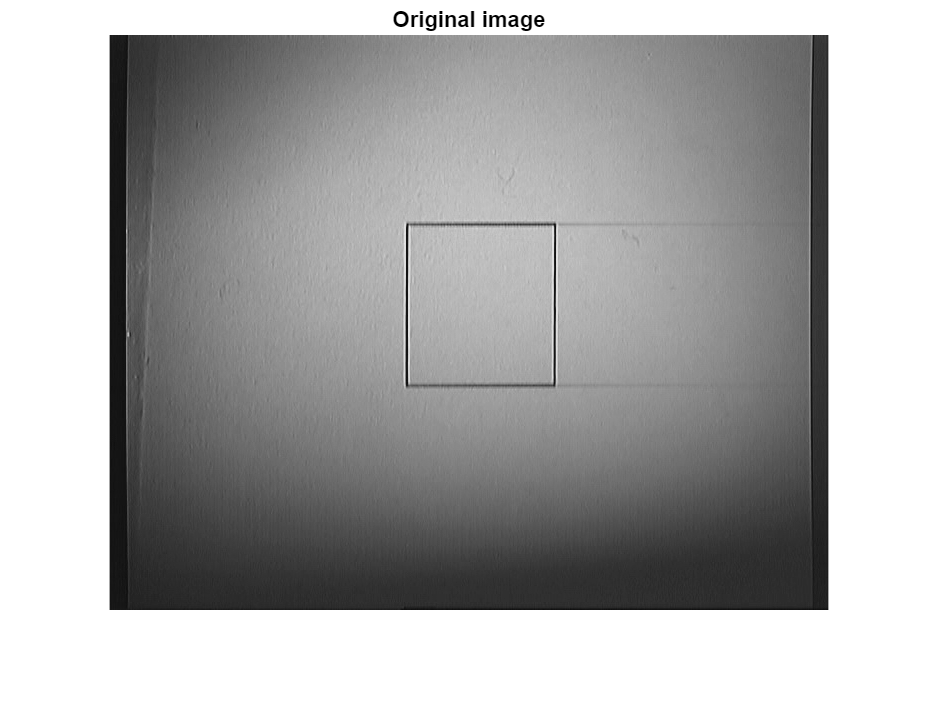

% Carica l'immagine
image = imread(['C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\' ...
    'Calibration_steps\pixels_to_world_coordinates\improvement_test\dark_720x576\test_accuratezza_user\prova2\quadrato.png']);

debug_on = true;

% Converti l'immagine in scala di grigi (se non lo è già)
if size(image, 3) == 3
    grayImage = rgb2gray(image);
else
    grayImage = image;
end

if debug_on
    figure
    imshow(grayImage)
    title('Original image')
end

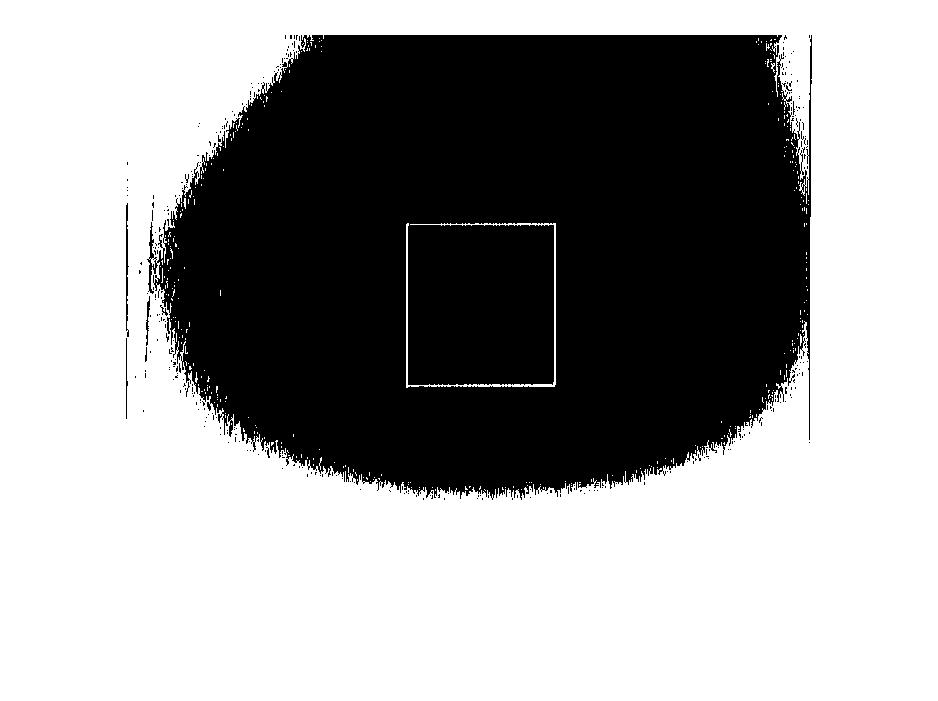

Icomplement = imcomplement(grayImage);
BW = imbinarize(Icomplement);

if debug_on
    figure
    imshow(BW)
end

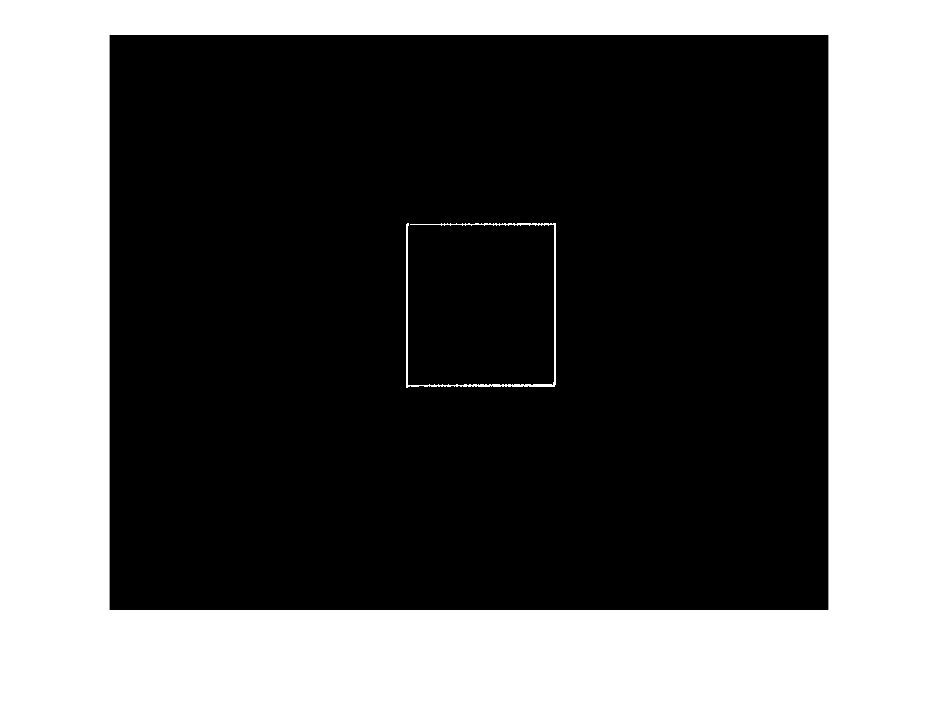


% Definisci una maschera per il quadrato centrale
[rows, cols] = size(grayImage);
centerMask = false(rows, cols);

% Definisci i limiti della regione centrale (ROI) 
centerRowStart = round(rows * 0.25);
centerRowEnd = round(rows * 0.70);
centerColStart = round(cols * 0.3);
centerColEnd = round(cols * 0.65);
centerMask(centerRowStart:centerRowEnd, centerColStart:centerColEnd) = true;
% Mantieni solo i bordi nella regione centrale
bordersCentral = BW & centerMask;

if debug_on
    figure
    imshow(bordersCentral)
end

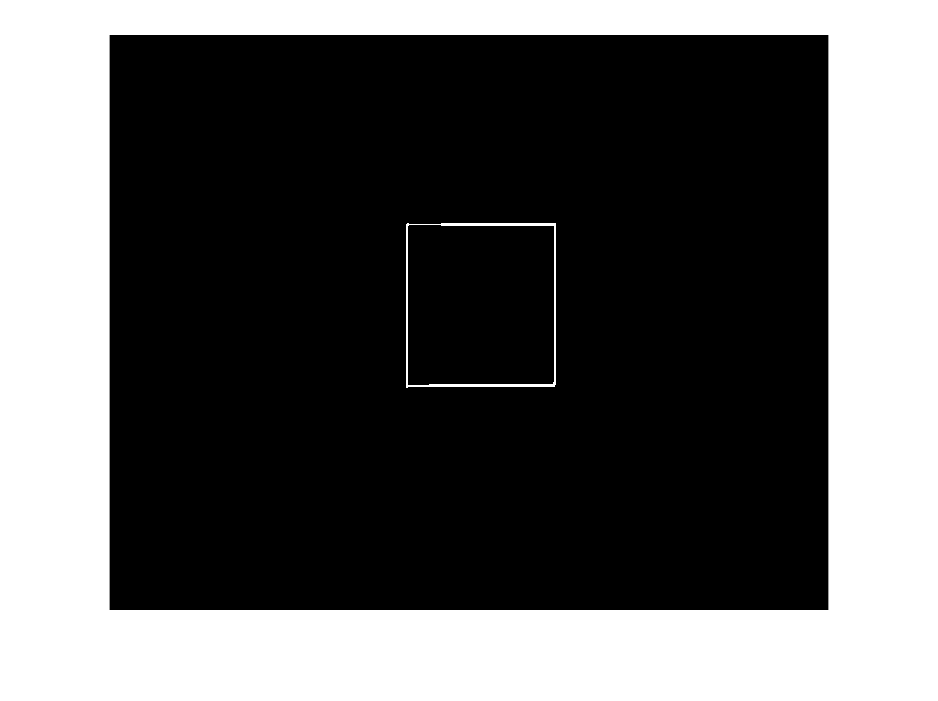

% Pulizia morfologica per eliminare artefatti
BWclean = bwmorph(bordersCentral, 'clean'); % Rimuove pixel isolati
% BWclean = bwmorph(BWclean, 'majority'); % Corregge piccoli buchi nei bordi
BWclean = imclose(BWclean, strel('square', 20)); % Chiude piccoli spazi nei bordi

if debug_on
    figure
    imshow(BWclean)
end

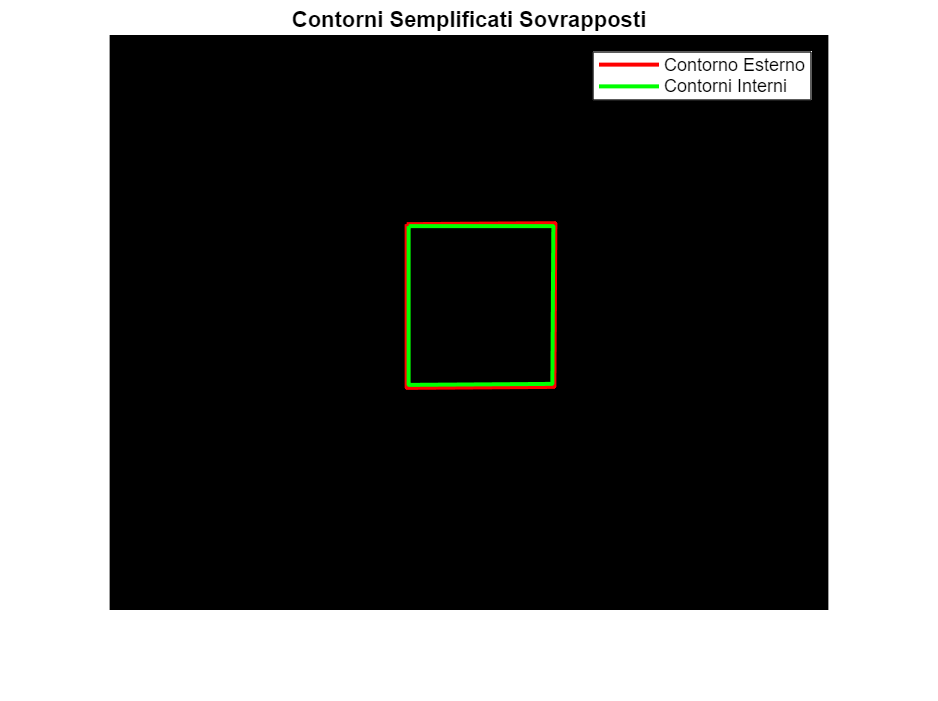

% Estrai i contorni con bwboundaries
boundaries = bwboundaries(BWclean, 'holes'); % 'holes' per includere contorni interni

% Contorno Esterno (Primo Contorno)
boundaryExternal = boundaries{1};
colExternal = boundaryExternal(:, 2);
rowExternal = boundaryExternal(:, 1);

% % Semplifica il contorno esterno usando Douglas-Peucker
tolerance = 0.009; % Tolleranza per semplificare i contorni
simplifiedExternal = reducepoly([colExternal, rowExternal], tolerance);

% Salva le coordinate del contorno esterno
externalCoords = simplifiedExternal;

% Contorni Interni (dal secondo in poi)
internalCoords = {}; % Inizializza cell array per i contorni interni

for k = 2:length(boundaries)
    boundaryInternal = boundaries{k};
    colInternal = boundaryInternal(:, 2);
    rowInternal = boundaryInternal(:, 1);
    
    % % Semplifica il contorno interno usando Douglas-Peucker
    simplifiedInternal = reducepoly([colInternal, rowInternal], tolerance);
    
    % Salva le coordinate semplificate del contorno interno
    internalCoords{end+1} = simplifiedInternal;
end

% Visualizza i risultati
figure;
imshow(BWclean);
title('Contorni Semplificati Sovrapposti');
hold on;

% Plot del contorno esterno
plot(externalCoords(:, 1), externalCoords(:, 2), 'r-', 'LineWidth', 2);

% Plot dei contorni interni
for k = 1:length(internalCoords)
    plot(internalCoords{k}(:, 1), internalCoords{k}(:, 2), 'g-', 'LineWidth', 2);
end

legend('Contorno Esterno', 'Contorni Interni');
hold off;

#### Interpola i bordi del target

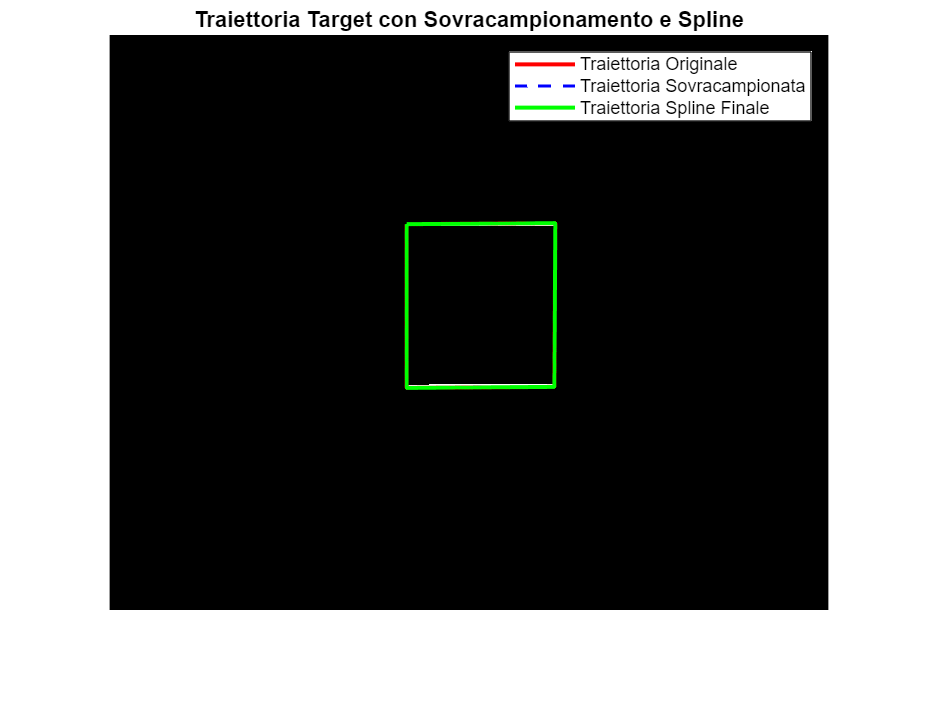

% % Carica le coordinate semplificate salvate
% load('contour_coordinates.mat'); % Carica externalCoords e internalCoords

% Seleziona il contorno target (es: contorno esterno)
trajectoryCoords = externalCoords;

% Passo 1: Sovracampionamento della traiettoria semplificata
numPoints = 100 * size(trajectoryCoords, 1); % Aumenta il numero di punti (ad esempio 5x)
tOriginal = 1:size(trajectoryCoords, 1);
tOversampled = linspace(1, size(trajectoryCoords, 1), numPoints);

xOversampled = interp1(tOriginal, trajectoryCoords(:,1), tOversampled, 'linear');
yOversampled = interp1(tOriginal, trajectoryCoords(:,2), tOversampled, 'linear');

% Passo 2: Interpolazione spline sulla traiettoria sovracampionata
tSpline = linspace(1, numPoints, numPoints * 2); % Ulteriore interpolazione spline
xSpline = interp1(1:numPoints, xOversampled, tSpline, 'spline');
ySpline = interp1(1:numPoints, yOversampled, tSpline, 'spline');

% Visualizza la traiettoria target
figure;
imshow(BWclean);
title('Traiettoria Target con Sovracampionamento e Spline');
hold on;

% Plot della traiettoria originale semplificata
plot(trajectoryCoords(:,1), trajectoryCoords(:,2), 'r-', 'LineWidth', 2);

% Plot della traiettoria sovracampionata
plot(xOversampled, yOversampled, 'b--', 'LineWidth', 1.5);

% Plot della traiettoria spline finale
plot(xSpline, ySpline, 'g-', 'LineWidth', 2);
legend('Traiettoria Originale', 'Traiettoria Sovracampionata', 'Traiettoria Spline Finale');
hold off;

% Salva la traiettoria target come coordinate
% trajectoryTarget = [xInterp', yInterp'];
% save('trajectory_target.mat', 'trajectoryTarget');

#### Protietta il taget nel mondo

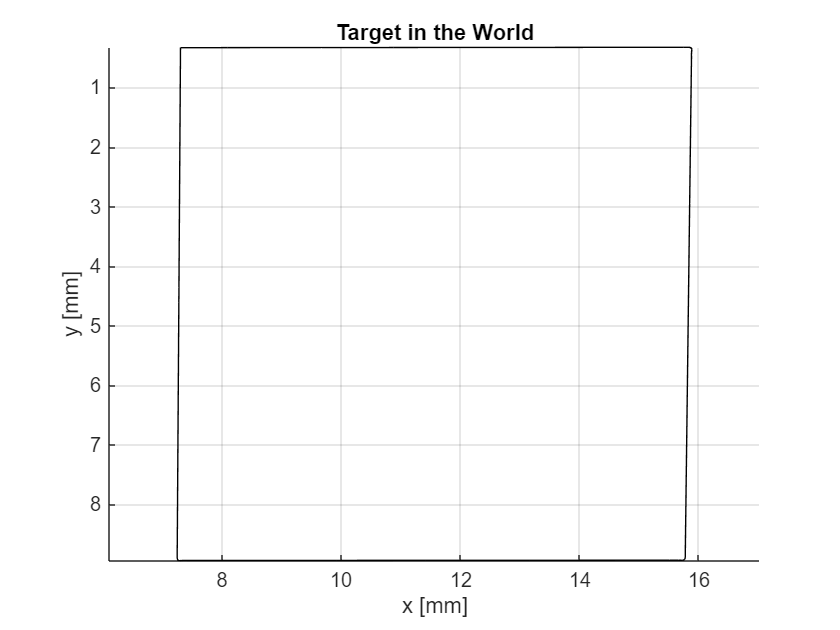

load("C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\" + ...
    "Materiale\PROGETTO CALM\Caratterizzazione CALM\Calibration_steps\pixels_to_world_coordinates\" + ...
    "improvement_test\calibrazione_720_576\dati di calibrazione\calm_camera_calibration.mat");

intrinsics = calm_camera_calibration.Instrinsics_params;
extrinsics = calm_camera_calibration.Extrinsics_params;

load("C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\" + ...
    "Materiale\PROGETTO CALM\Caratterizzazione CALM\Calibration_steps\pixels_to_world_coordinates\" + ...
    "improvement_test\calibrazione_720_576\CameraCalibratorApp\cameraParams.mat");

TargetCoordinatesSmoothed = [xSpline', ySpline']; 
skeletonWorldCoordinates = zeros(length(TargetCoordinatesSmoothed), 2);
 
for i = 1:length(TargetCoordinatesSmoothed)

    skeletonWorldCoordinates(i,:) = img2world2d(TargetCoordinatesSmoothed(i,1:2), extrinsics, intrinsics); % millimetri

end

% Plot della traiettoria nel mondo
figure
plot(skeletonWorldCoordinates(:,1), skeletonWorldCoordinates(:,2),'k');
hold on
set(gca, 'YDir', 'reverse'); % Invertiamo l'asse Y per riflettere il piano mondo
xlabel 'x [mm]'
ylabel 'y [mm]'
axis equal;
grid on;

title('Target in the World')
box off

folder = ['C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\' ...
    'Calibration_steps\pixels_to_world_coordinates\improvement_test\dark_720x576\test_accuratezza_user\test2'];

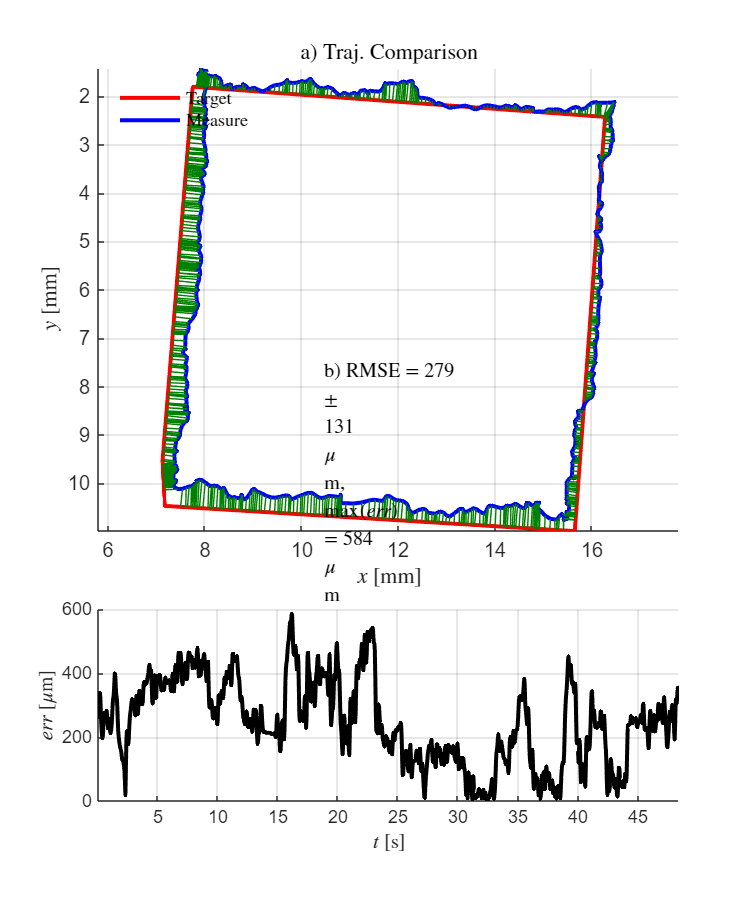

RMSE     = 279 ± 131 µm
max(err) = 584 µm


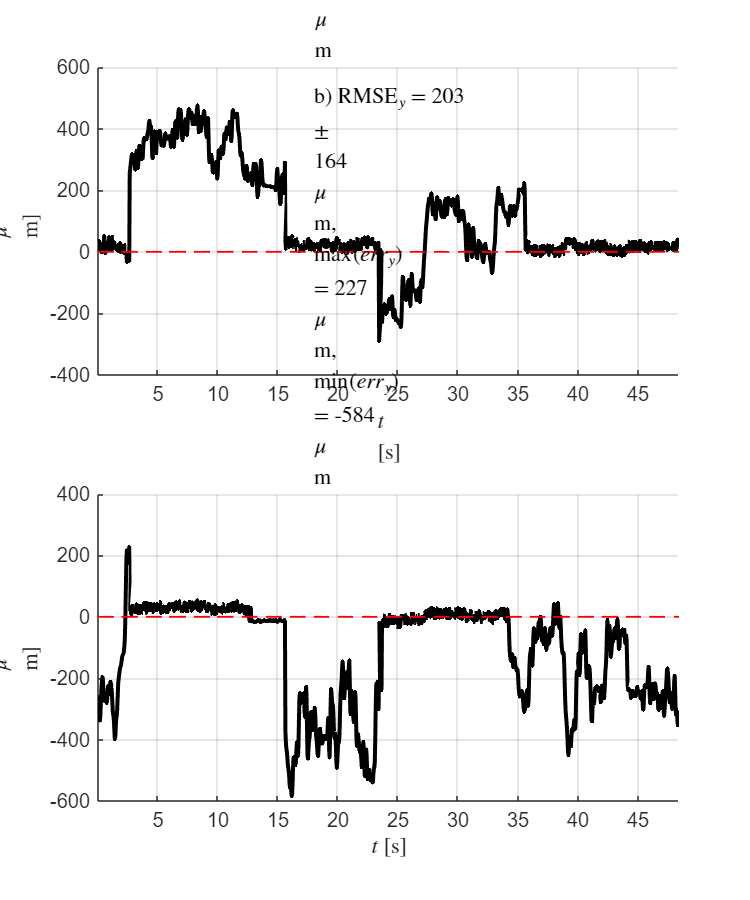

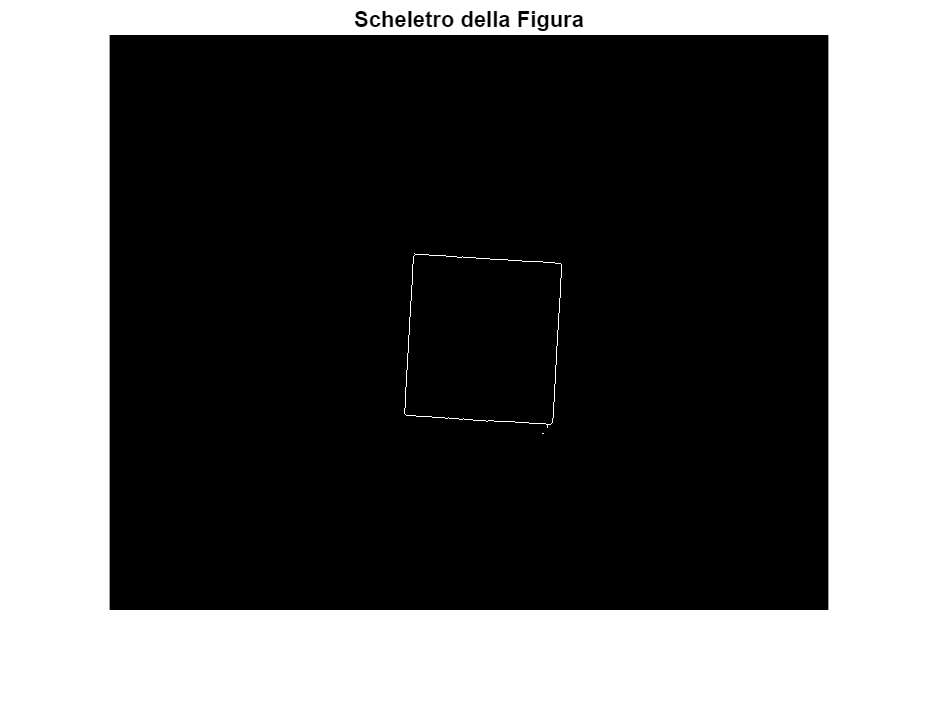

% t is time
xt = skeletonWorldCoordinates(:,1);
yt = skeletonWorldCoordinates(:,2);

t = (1:1:length(coords_matrix(:,2)))'/ video.FrameRate;
[rmse, std, err] = circ_rmse(xt, yt, laserWorldPoints_filtered(:,1) ,laserWorldPoints_filtered(:,2), t);